## Tutorial 5.1

Se creó la función** lagc.m**

clc; clear all; close all;

% test.m
p=1;
N=3;
[Ap,L0]=lagc(p,N);
delta_t=0.01;
Tm=8;
N_sample=Tm/delta_t;
t=0:delta_t:(N_sample-1)*delta_t;
%solution of the differential equation
for i=1:N_sample
    L(:,i)=expm(Ap*t(i))*L0;
end
figure
plot(t,L(1,:),t,L(2,:),'--',t,L(3,:),'.')
xlabel('Time (sec)')

## Tutorial 5.2

Se creó la función **inte.m**

Se creó la función** lagmodel.m**

clc; clear all; close all;

% lagmodel.m

p=1;
N=4;
delta_t=0.01;
Tm=8;
N_sample=Tm/delta_t;
t=0:delta_t:(N_sample-1)*delta_t;
[Ap,L0]=lagc(p,N);
for i=1:N_sample
    L(:,i)=expm(Ap*t(i))*L0;
end

num=1;

num = 1

den=conv([1 1],[1 2]);

den =      1     3     2


h_t=impulse(num,den,t)'

h_t =          0    0.0099    0.0194    0.0287    0.0377    0.0464    0.0548    0.0630    0.0710    0.0787    0.0861    0.0933    0.1003    0.1070    0.1136    0.1199    0.1260    0.1319    0.1376    0.1431    0.1484    0.1535    0.1585    0.1632    0.1678    0.1723    0.1765    0.1806    0.1846    0.1884    0.1920    0.1955    0.1989    0.2021    0.2052    0.2081    0.2109    0.2136    0.2162    0.2187    0.2210    0.2232    0.2253    0.2273    0.2293    0.2311    0.2328    0.2344    0.2359    0.2373


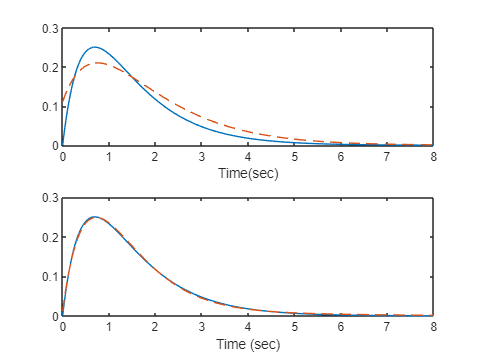


hL_1=L(1,:).*h_t;
c1=inte(hL_1,delta_t);              

hL_2=L(2,:).*h_t;
c2=inte(hL_2,delta_t);

hL_3=L(3,:).*h_t;
c3=inte(hL_3,delta_t);

hL_4=L(4,:).*h_t;
c4=inte(hL_4,delta_t);

h_model2=c1*L(1,:)+c2*L(2,:);
h_model4=c1*L(1,:)+c2*L(2,:)+c3*L(3,:)+c4*L(4,:);

figure 
subplot(211)
plot(t,h_t,t,h_model2,'--');
xlabel('Time(sec)')

subplot(212)
plot(t,h_t,t,h_model4,'--');
xlabel('Time (sec)')